clear; clc; clearvars;
syms vin vout s c r w H a denHreal denH numH positive

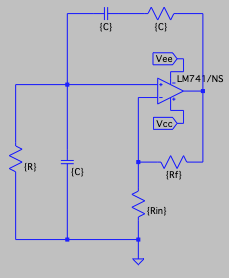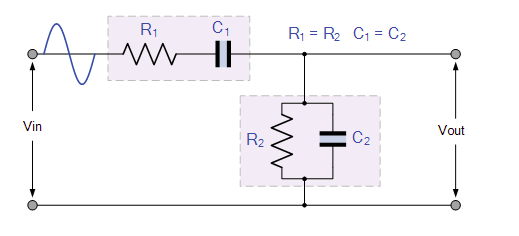

Como esse é um circuito mais simples é poossivel encontrar a relação Vout/Vin a partir de um divisor de tensão. Para tal é preciso antes simplificar R e C que estão em paralelo. 

Em seguida, se usa a formula levando em consideracao que a tensao total é Vin e a parcial Vout

paralRC = paraleloSym(r, 1/(s*c));
eq = vin*paralRC/(paralRC + r + 1/(s*c)) - vout == 0

$$eq = \frac{\mathrm{vin}}{\left(c\,s+\frac{1}{r}\right)\,\left(r+\frac{1}{c\,s+\frac{1}{r}}+\frac{1}{c\,s}\right)}-\mathrm{vout}=0$$

Isolando vin/vout para obter H

H = solve(eq, vout) / vin

$$H = \frac{c\,r\,s}{c^{2}\,r^{2}\,s^{2}+3\,c\,r\,s+1}$$

Feito isso precisamos separar o denominador do numerador

[numH, denH] = numden(H)

$$numH = c\,r\,s$$

$$denH = c^{2}\,r^{2}\,s^{2}+3\,c\,r\,s+1$$

Fazendo s=jw para voltar ao domínio do tempo

s = 1i*w;
numH = subs(numH);
denH = subs(denH);
H = numH/denH

$$H = \frac{c\,r\,w\,\mathrm{i}}{-c^{2}\,r^{2}\,w^{2}+3\,c\,r\,w\,\mathrm{i}+1}$$

Como o objetivo é que a função de transferência não gere defasagem, igualamos a parte real do denominador a zero.

denHreal = subs(denH, 1i, 0);

Atualizando a função pai

denH = denH - denHreal;

No caso dessa função de transferência o valor de H com a parte real anulada já resulta em 1/3, que equivale ao nosso A.

H = numH/denH

$$H = \frac{1}{3}$$

Agora vamos encontrar a frequencia para a qual o A é de 1/3

denHreal = denHreal == 0

$$denHreal = 1-c^{2}\,r^{2}\,w^{2}=0$$

  w = solve(denHreal, w);
  w = simplify(w)   

$$w = \frac{1}{c\,r}$$

Como é mais comum trabalharmos com a frequencia em Hz a equação pode ser escrita também da seguinte forma:


$$f=\frac{1}{2\;\pi \;C\;R}$$
